# Example VLM and DLM analysis script

clear all; close all; clc;

## 0. Add tool box path

Firstly, the code has to set the system path for useable functions. 

addpath(fullfile(pwd,'examples'))
addpath(fullfile(pwd,'panel_tools'))
addpath(fullfile(pwd,'vlm_dlm'))

## 1. Import input function script

- Select the input function script for analysis. The example name ex5_AC_full.m is assigned in this analysis.

nameACscript = 'ex5_AC_full';

## 2. Generate Aerodynamic panel

- The aerodynamic panels have to be created by PanelGen function. Inside of this function there are three main functional process including 

- Translating structural grids into aerodynamic panels

- Mapping and shifting the aerodynamic panels

- Create the lattice panels from aerodynamic panels

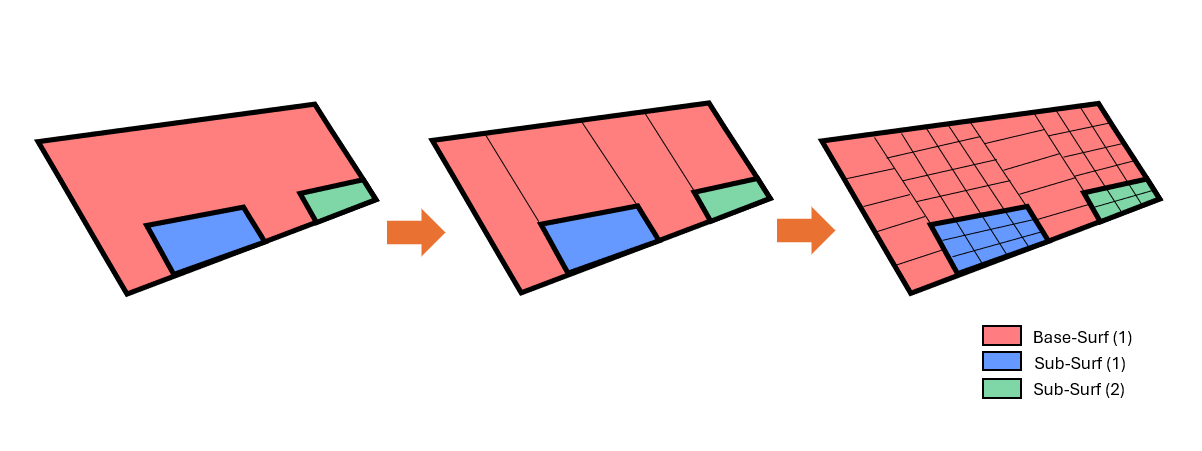

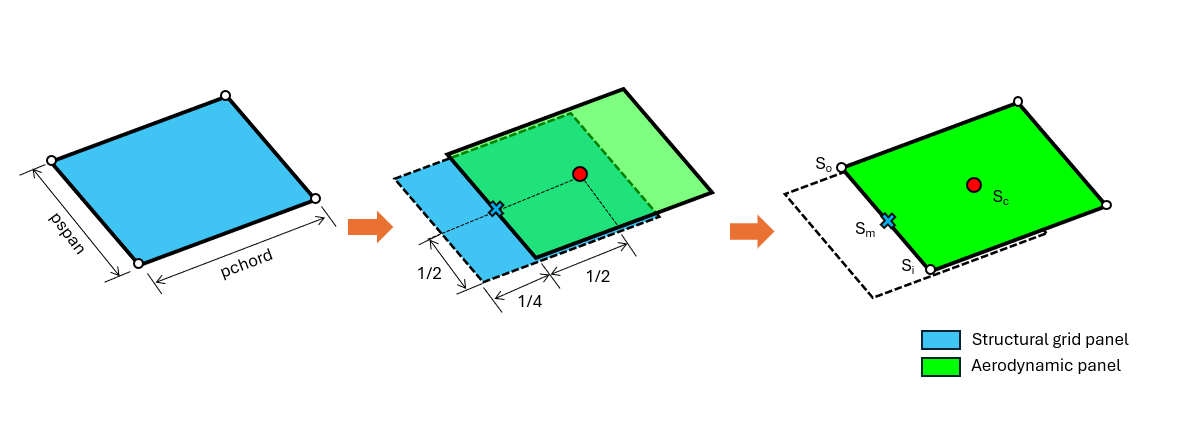

% PanelGen
[PanelDat,FC,Sc,Sm,Si,So,S,pspan,pchord,normvec] = ...
    PanelGen(nameACscript);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%% Input variables %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% AC            (-) Aircraft Configuration data
% FC            (-) Flight Conditions data

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%% Output variables %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PanelDat      (-) Generated Panel data
% Sc            (m) [x y z] Collocation point 
% Sm            (m) [x y z] Vortex point
% Si            (m) [x y z] A point at left side of bound vortex
% So            (m) [x y z] A point at right side of bound vortex
% S             (m^2) Area of panel
% pspan         (m)  Span of panel
% pchord        (m)  Chord of panel
% normvec       (-) [u v w] Normal vector


## 3. Vortex Lattice method (VLM) analysis

For VLM function, the input are variables from PanelGen function where are two group of fight conditions and panel parameters analysis like vortex and collocation points, areas and spans of panel, and normal vectors.

% VLM
[D0,A,GAMMA,F_VLM,M_VLM] = ...
    VLM(FC.rG,FC.M,FC.Qinf,FC.rho_air,...
    Sc,Sm,Si,So,S,pspan,normvec);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%% Input variables %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% rG            (m) Center of mass of aircraft
% M             (-) Mach number
% Qinf          (m/s) [x y z] Velocity for static loadings
% rho_air       (kg/m^3) Density of air
% Sc            (m) [x y z] Collocation point 
% Sm            (m) [x y z] Vortex point
% Si            (m) [x y z] A point at left side of bound vortex
% So            (m) [x y z] A point at right side of bound vortex
% S             (m^2) Area of panel
% pspan         (m)  Span of panel
% normvec       (-) [u v w] Normal vector

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%% Output variables %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% D0            ()  Induced velocity with covering with geometrical
% A             ()  Induced velocity
% GAMMA         ()  Vortex strength
% F_VLM         (N)   [Fx Fy Fz] Force
% M_VLM         (N*m) [Mx My Mz] Moment (ref. center of mass)


## 4. Doublet Lattice method (DLM) analysis

- DLM function is require the input variable similar to VLM function. The reduced frequency is additive variable to solve in term of transient. The DLM function either require D0 solution from VLM function or not is necessary.

% DLM
D = DLM(Sc,Si,Sm,So,FC.M,FC.k,pchord,D0);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%% Input variables %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% M             (-) Mach number
% k             (-) Reduced frequency
% rho_air       (kg/m^3) Density of air
% Sc            (m) [x y z] Collocation point 
% Sm            (m) [x y z] Vortex point
% Si            (m) [x y z] A point at left side of bound vortex
% So            (m) [x y z] A point at right side of bound vortex
% S             (m^2) Area of panel
% pspan         (m)  Span of panel
% normvec       (-) [u v w] Normal vector


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%% Output variables %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% D             (-) Induced velocity with covering with geometrical
%                   at each reduced frequency


## 5. Result Analysis

Calculate the downwash from normal vectors

W = (FC.Qinf(1)*normvec(:,1) + ...
     FC.Qinf(2)*normvec(:,2) + ...
     FC.Qinf(3)*normvec(:,3))/norm(FC.Qinf);

Calculate pressure cofficients from VLM

% Calculate Cp of steady part
Ajj_VLM = D0;
Qjj_VLM = -inv(Ajj_VLM);
Cp_VLM = Qjj_VLM*W;

Calculate pressure cofficients from DLM

% Calculate Cp of unsteady part
Nk = numel(FC.k); % Number of Reduced Frequencies
Cp_DLM = cell(1,Nk);
for i = 1:Nk
    Cp_DLM{i} = -inv(D{i})*W; % Calculate Cp of each reduced frequency
end

Summarizing lift (Fz), drag (Fx) and sideslip (Fy) forces and moments

% Summation of Forces and Moments
F_VLM_total = sum(F_VLM,1);
M_VLM_total = sum(M_VLM,1);

disp(['Fx_total = ' num2str(F_VLM_total(1),'%1.2f'),' N']);

Fx_total = -20.13 N


disp(['Fy_total = ' num2str(F_VLM_total(2),'%1.2f'),' N']);

Fy_total = 48.26 N


disp(['Fz_total = ' num2str(F_VLM_total(3),'%1.2f'),' N']);

Fz_total = 1328.57 N


disp(['Mx_total = ' num2str(M_VLM_total(1),'%1.2f'),' N*m']);

Mx_total = -2539.64 N*m


disp(['My_total = ' num2str(M_VLM_total(2),'%1.2f'),' N*m']);

My_total = -4015.81 N*m


disp(['Mz_total = ' num2str(M_VLM_total(3),'%1.2f'),' N*m']);

Mz_total = 235.53 N*m


Plotting results

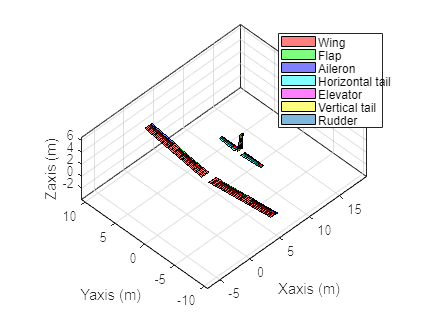

% Plot characteristics of generated aircraft panels results
plot_panel(PanelDat);
set(gca,'View',[-45,45])

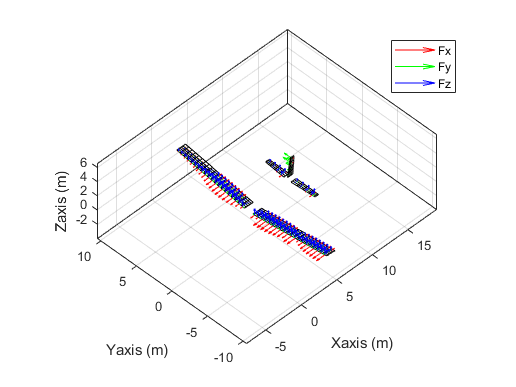

% Plot Force acting on aircraft panels
plot_F(PanelDat,F_VLM);
set(gca,'View',[-45,45])

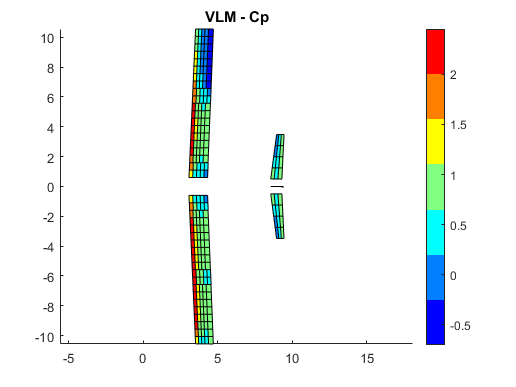

% Plot Cp_VLM results
GOBJ1 = plot_Cp(PanelDat,Cp_VLM);
set(GOBJ1.ax,'View',[0,90])

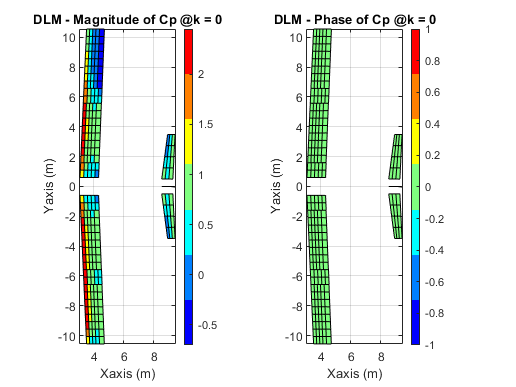

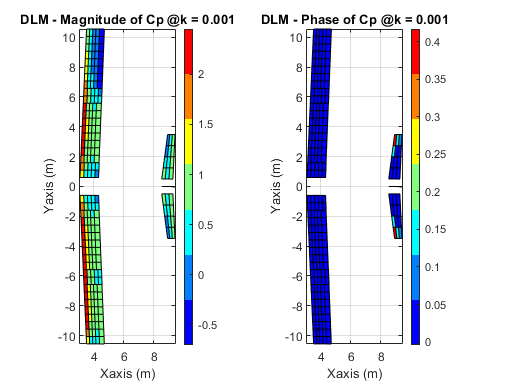

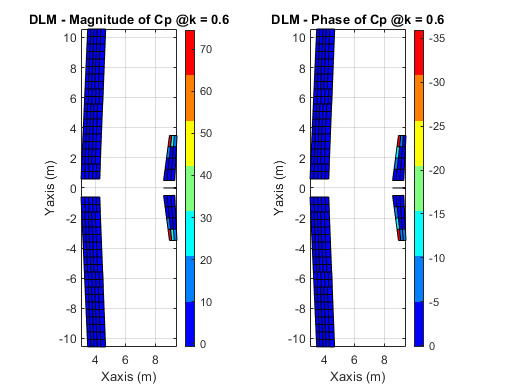

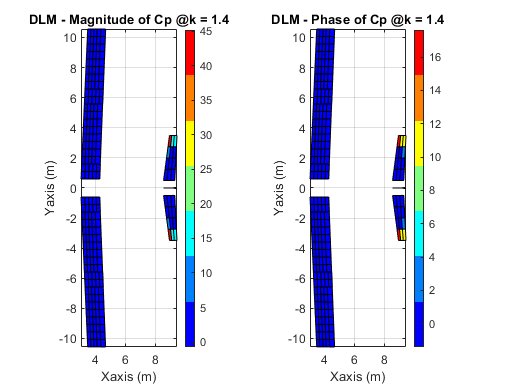

% Plot Cp_DLM results
GOBJ2 = plot_Cp(PanelDat,Cp_DLM,FC.k);
for i = 1:size(GOBJ2.ax,1)
    set(GOBJ2.ax{i,1},'View',[0,90])
    set(GOBJ2.ax{i,2},'View',[0,90])
end

0;